%% QUESTAO 4
clear; clc; close all;

%% a) Determinacao da Função de Transferência
p_mag = 0.85;
theta = pi/5;
z0 = -0.6;

% Polos complexos conjugados
p1 = p_mag * exp(1i * theta);
p2 = p_mag * exp(-1i * theta);

% Coeficientes do denominador: (1 - p1*z^-1)(1 - p2*z^-1) = 1 + a1*z^-1 + a2*z^-2
a1 = -2 * p_mag * cos(theta);
a2 = p_mag^2;
a = [1, a1, a2];

% Calculo de K para H(1) = 1: H(1) = K*(1 + 0.6) / (1 + a1 + a2) = 1
K = (1 + a1 + a2) / (1 + 0.6);

% Coeficientes do numerador: b0 + b1*z^-1
b0 = K;
b1 = K * 0.6;
b = [b0, b1];

fprintf('--- Item (a) Coeficientes ---\n');

--- Item (a) Coeficientes ---


fprintf('K  = %.5f\n', K);

K  = 0.21698


fprintf('b  = [%.5f, %.5f]\n', b(1), b(2));

b  = [0.21698, 0.13019]


fprintf('a  = [%.5f, %.5f, %.5f]\n\n', a(1), a(2), a(3));

a  = [1.00000, -1.37533, 0.72250]



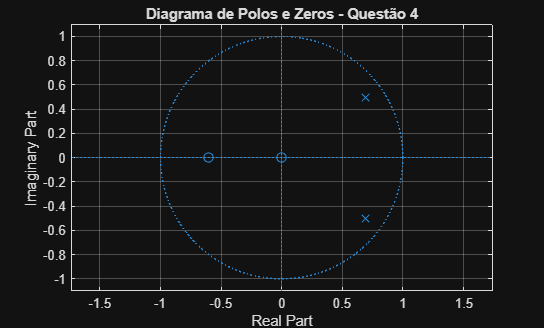


%% b) Polos, Zeros, Diagrama e Propriedades
figure('Name', 'Diagrama de Polos e Zeros');
zplane(b, a);
grid on;
title('Diagrama de Polos e Zeros - Questão 4');

%% d) e e) Implementacao Direta
% Definindo entrada x[n] para validação da resposta ao impulso (n = 0 a 59)
N_imp = 60;
n_imp = 0:(N_imp - 1);
x_imp = [1, zeros(1, N_imp - 1)];

% Condições iniciais nulas para item (f)
estado_inicial = [0, 0]; % [y[-1], y[-2]]
[y_algoritmo, estado_final] = filtro_iir_direto(x_imp, n_imp, b, a, estado_inicial);

%% f) Resposta ao Impulso Analítica e Comparação
% Expressão analítica em forma fechada: h[n] = K * r^n * [cos(theta*n) + ((0.6 + cos(theta))/sin(theta)) * sin(theta*n)] * u[n]
% Obtida decompondo H(z) em componentes cosseno e seno
C_cos = K;
C_sen = K * (0.6 + cos(theta)) / sin(theta);
h_analitico = (p_mag.^n_imp) .* (C_cos * cos(theta * n_imp) + C_sen * sin(theta * n_imp));

E_max = max(abs(y_algoritmo - h_analitico));
fprintf('--- Item (f) Validação ---\n');

--- Item (f) Validação ---


fprintf('Erro máximo absoluto (E_max) = %e\n\n', E_max);

Erro máximo absoluto (E_max) = 2.685794e-02



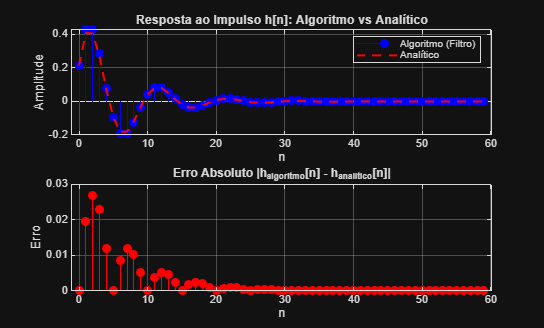


figure('Name', 'Item (f) Resposta ao Impulso');
subplot(2,1,1);
stem(n_imp, y_algoritmo, 'filled', 'b'); hold on;
plot(n_imp, h_analitico, 'r--', 'LineWidth', 1.5);
title('Resposta ao Impulso h[n]: Algoritmo vs Analítico');
xlabel('n'); ylabel('Amplitude');
legend('Algoritmo (Filtro)', 'Analítico'); grid on;

subplot(2,1,2);
stem(n_imp, abs(y_algoritmo - h_analitico), 'r', 'filled');
title('Erro Absoluto |h_{algoritmo}[n] - h_{analítico}[n]|');
xlabel('n'); ylabel('Erro'); grid on;

%% g) e h) Resposta a um Sinal Composto
rng(1); % Garantir reprodutibilidade
N_comp = 400;
n_comp = 0:(N_comp - 1);

w = randn(1, N_comp); % Ruído gaussiano N(0,1)
x_comp = cos(pi*n_comp / 5) + 0.5*cos(4*pi*n_comp / 5) + 0.15*w;

% Filtragem usando a função customizada
[y_comp, ~] = filtro_iir_direto(x_comp, n_comp, b, a, [0, 0]);

% Comparação com a função nativa 'filter' para validação de erro
y_nativo = filter(b, a, x_comp);
erro_comp = max(abs(y_comp - y_nativo));
fprintf('--- Item (g) Erro Máximo vs Implementação Nativa ---\n');

--- Item (g) Erro Máximo vs Implementação Nativa ---


fprintf('Erro máximo relativo entre filtro customizado e filter(): %e\n\n', erro_comp);

Erro máximo relativo entre filtro customizado e filter(): 1.443290e-15




figure('Name', 'Item (g) Resposta ao Sinal Composto');
subplot(3,1,1);
plot(n_comp(1:80), x_comp(1:80), 'b', 'LineWidth', 1.2);
title('Entrada x[n] (Primeiras 80 amostras)');
xlabel('n'); ylabel('Amplitude'); grid on;

subplot(3,1,2);
plot(n_comp(1:80), y_comp(1:80), 'r', 'LineWidth', 1.2);
title('Saída y[n] (Primeiras 80 amostras)');
xlabel('n'); ylabel('Amplitude'); grid on;

%% i) Condições Iniciais Não-Nulas
y_menos1 = 1;
y_menos2 = -0.5;

% 1. Resposta com Condições Iniciais (Entrada + CI)
[y_CI_total, ~] = filtro_iir_direto(x_comp, n_comp, b, a, [y_menos1, y_menos2]);

% 2. Resposta de Entrada Nula (x[n] = 0, apenas CI)
[y_entrada_nula, ~] = filtro_iir_direto(zeros(size(x_comp)), n_comp, b, a, [y_menos1, y_menos2]);

% 3. Resposta de Repouso Inicial (CI = 0, calculada no item g) -> y_comp

% Verificação: y_zi[n] = y_CI_total[n] - y_repouso[n]
y_zi_diferenca = y_CI_total - y_comp;

figure('Name', 'Item (i) Condições Iniciais');
subplot(2,1,1);
plot(n_comp(1:100), y_CI_total(1:100), 'k', 'LineWidth', 1.2); hold on;
plot(n_comp(1:100), y_comp(1:100), 'b--', 'LineWidth', 1.2);
plot(n_comp(1:100), y_entrada_nula(1:100), 'r-.', 'LineWidth', 1.2);
title('Decomposição da Resposta com Condições Iniciais');
xlabel('n'); ylabel('Amplitude');
legend('Total (Com CI)', 'Estado Nulo (Sem CI)', 'Entrada Nula (Apenas CI)'); grid on;

subplot(2,1,2);
plot(n_comp(1:100), y_entrada_nula(1:100), 'r', 'LineWidth', 1.5); hold on;
plot(n_comp(1:100), y_zi_diferenca(1:100), 'k--', 'LineWidth', 1);
title('Validação da Resposta de Entrada Nula: y_{zi}[n] = y_{total}[n] - y_{repouso}[n]');
xlabel('n'); ylabel('Amplitude');
legend('y_{zi} Direto (x=0)', 'y_{total} - y_{repouso}'); grid on;



%% FILTRAGEM IIR DIRETA (Itens c, d, e)
function [y, estado_final] = filtro_iir_direto(x, nx, b, a, estado_inicial)
    % Validação de compatibilidade
    if length(x) ~= length(nx)
        error('Os vetores de entrada x e índices nx devem ter o mesmo tamanho.');
    end

    N = length(x);
    y = zeros(1, N);
    
    % Normalização dos coeficientes em a(1)
    b0 = b(1) / a(1);
    b1 = b(2) / a(1);
    a1 = a(2) / a(1);
    a2 = a(3) / a(1);
    
    % Inicialização dos registradores de memória com condições iniciais
    % estado_inicial = [y[-1], y[-2]]
    y_m1 = estado_inicial(1);
    y_m2 = estado_inicial(2);
    x_m1 = 0; % Presume-se repouso para a entrada anterior
    
    % Algoritmo de diferenças ponto a ponto
    for n = 1:N
        % Equação de diferenças: y[n] = b0*x[n] + b1*x[n-1] - a1*y[n-1] - a2*y[n-2]
        y(n) = b0 * x(n) + b1 * x_m1 - a1 * y_m1 - a2 * y_m2;
        
        % Atualização dos estados para a próxima iteração
        x_m1 = x(n);
        y_m2 = y_m1;
        y_m1 = y(n);
    end
    
    estado_final = [y_m1, y_m2];
end